# Practice 1: Forward Kinematics on SCARAv3

## Objective:

    to solve and to create the Denavit Hartenberg Matrix to simplify the following Transformation of the Mechanical Manipulator (In this case, SCARAV3)

## Algorithm:

    1. Identify the Link Length

    2. Create a Denavit Hartenberg Paramteric Table

    3. Plug-in the Matrix of the following Manipulator

    4. Matrix Multiply the Transformation Matrices.

## Conventions Used:

    a_<number> - Constant Link Length

    theta = Joint Offset

    alpha = Link Twist

    r = Link Length

    d = Link Offset

### Display the Lengths

disp("SCARAV3")

SCARAV3



syms a1 a2 a3 a4

% Link Lengths a1 to a4

a1 = 500;
a2 = 300;
a3 = 400;
a4 = 300;

### Defining the DH Parameters

In, Python, we tend to compute the Matrix of it based on the specific angles given. Since in Reality, Mechanical Manipulators tend not to work on this way. We must program a mathematical model of machanical manipulators to visualize the movement itself.

% Take note of theta, alpha, r/a, and d
H_01 = Prismatic()

 
H_01 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=0


H_12 = Revolute('a', a2)

 
H_12 = 
Revolute(std): theta=q, d=0, a=300, alpha=0, offset=0


H_23 = Revolute('a', a4, 'd', a3)

 
H_23 = 
Revolute(std): theta=q, d=400, a=300, alpha=0, offset=0



%Defining the Joint Limits (IRL it has following limits of course)

H_01.qlim = [0, 100];
H_12.qlim = pi/180 * [-90, 90];
H_23.qlim = pi/180 * [-90, 90];

### Combining the DH Parameters into a `SerialLink` object

Once created the following DH Parameters, we can connect using a SerialLink object. This displays the DH Parametric Table we've discussed in Robotics 1

SCARAv3 = SerialLink([H_01, H_12,H_23], 'name', 'SCARAV3')

 
SCARAv3 = 
 
SCARAV3:: 3 axis, PRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|          0|          0|
|  2|         q2|          0|        300|          0|          0|
|  3|         q3|        400|        300|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Plotting and Teaching the Robot

Once done, we are about to plot the robot in the origin, and teach the robot (Have Sliders to know the position of the end effector based on the jont angles)

origin = [0 0 0]

origin =      0     0     0


workspace = [-750, 750, -750, 750, -750, 750]

workspace =   -750   750  -750   750  -750   750


SCARAv3.plot(origin, 'workspace', workspace)

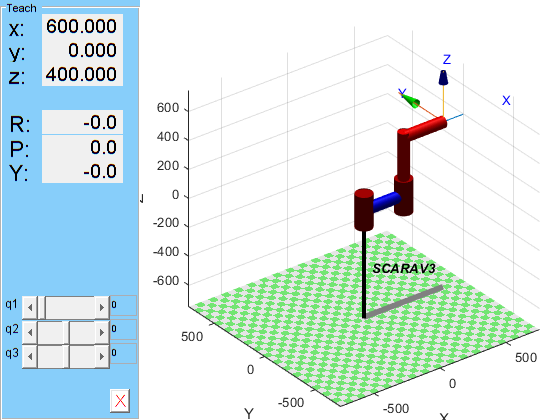

SCARAv3.teach()